# Miniprojekt 3 - Tone Control

## Indledning

VIl vil i denne opgave vil vi anvende digital signalbehandling til at justere lyden i en Lyngdorf TDAI-1120 forstærker. Vi vil arbejde audiofiltre og lgoritmer til at opnå en løsning. Forstærkeren indeholder en DSP med forskellige features som tonecontrol, Room Correction og Speaker EQ. Vi vil i denne opgave arbejde med Tone Control. 

## Formål

Vi vil analysere og designe tonekontrol som skal kunne ændre på gain af hhv. bassen og diskanten. Tonekontrol er det førsteled i DSP'en som ses i billedet nedenfor.

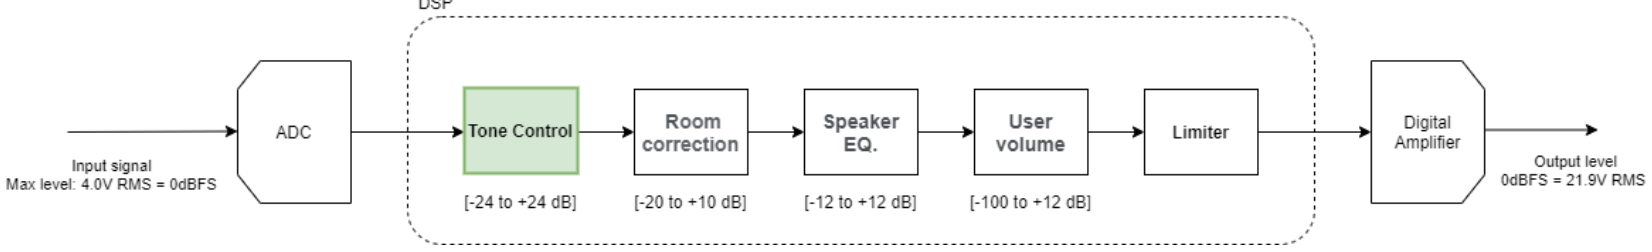

Dette vil vi gøre ved at konstruere to shelving-filtre i kaskade hvor den ene er til bas og den anden til diskant. Kravene er således:

- 2 x IIR filtre (shelving)

- Niveau i hvert bånd +-24dB

## Analyse

Først tages udgangspunkt i diskanten. Ved diskanten skal de høje frekvenser igennem, dvs. et højpas filter skal konstrueres.

**Set up the Parameters**

Fs  = 44100;    % Sampelfrekvens                            
Fcb = 100;      % Cutoff for bass
Fct = 1600;     % Cutoff for diskant

gainDiskant = 24;
gainBas = -12;



Fc = 150/(Fs/2);
K = tan(pi*Fc/Fs);
V0 = 10^(gainDiskant/20);

**Define the Tangent Frequency Mapping Parameters**

basstan   = tan(pi*Fcb/Fs);     % K konstant for bass
trebletan = tan(pi*Fct/Fs);     % K konstant for diskant

dbrange  = [-24:-1, +1:+24];    % -24 dB to +24 dB 
linrange = 10.^(dbrange/20);    % Konverter dB til lineær gain
boost = linrange(linrange>1);   % Separare boost
cut   = linrange(linrange<=1);  % Separare cut
Nfilters = 2 * length(dbrange); % 2X for bass and treble 



**Design the Filter Bank**

b0=(1+sqrt(2*V0)*K+K^2)/(1+sqrt(2)*K+K^2);
b1=(2*(V0*K^2-1))/(1+sqrt(2)*K+K^2);
b2=(1-sqrt(2*V0)*K+K^2)/(1+sqrt(2)*K+K^2);
a1=(2*(K^2-1))/(1+sqrt(2)*K+K^2);
a2=((1-sqrt(2)*K+K^2))/(1+sqrt(2)*K+K^2);


a2_bass_boost    = (basstan - 1) / (basstan + 1);
b1_bass_boost   = 1 + ((1 + a2_bass_boost) .* (boost - 1)) / 2;
b2_bass_boost   = a2_bass_boost + ...
                  ((1 + a2_bass_boost) .* (boost - 1)) / 2;

a2_bass_cut      = (basstan - cut) / (basstan + cut);
b1_bass_cut     = 1 + ((1 + a2_bass_cut) .* (cut - 1)) / 2;
b2_bass_cut     = a2_bass_cut + ((1 + a2_bass_cut) .* (cut - 1)) / 2;

a2_treble_boost  = (trebletan - 1) / (trebletan + 1); 
b1_treble_boost   = 1 + ((1 - a2_treble_boost) .* (boost - 1)) / 2;
b2_treble_boost   = a2_treble_boost + ...
                    ((a2_treble_boost - 1) .* (boost - 1)) / 2;

a2_treble_cut      = (cut .* trebletan - 1) / (cut .* trebletan + 1);
b1_treble_cut     = 1 + ((1 - a2_treble_cut) .* (cut - 1)) / 2;
b2_treble_cut     = a2_treble_cut + ...
                    ((a2_treble_cut - 1) .* (cut - 1)) / 2;


**Build the Filter Bank**

                
filterbank = cell(1, 2*Nfilters);     % 2X for numerator and denominator
% Duplicate a2's into vectors
a2_bass_boost   = repmat(a2_bass_boost,   1, length(boost));
a2_bass_cut     = repmat(a2_bass_cut,     1, length(cut));
a2_treble_boost = repmat(a2_treble_boost, 1, length(boost));
a2_treble_cut   = repmat(a2_treble_cut,   1, length(cut));

filterbank_num = [b1_bass_cut, b1_bass_boost, b1_treble_cut, b1_treble_boost, b2_bass_cut, b2_bass_boost, b2_treble_cut, b2_treble_boost ]';
% a1 is always one
filterbank_den = [ones(1, Nfilters); ...
                  a2_bass_cut, a2_bass_boost, a2_treble_cut, a2_treble_boost]';

filterbank(1:2:end) = num2cell(filterbank_num, 2);
filterbank(2:2:end) = num2cell(filterbank_den, 2);


**Check the Response of the Filter Bank**

fvtool(filterbank{:}, 'FrequencyScale', 'log', 'Fs', Fs);